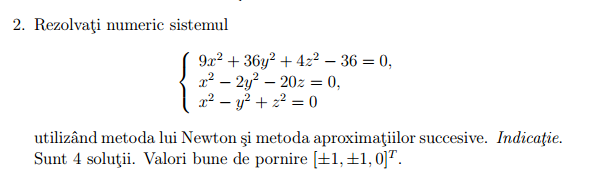

## Define system

F = @(v) [ 9*v(1)^2 + 36*v(2)^2 + 4*v(3)^2 - 36;
           v(1)^2 - 2*v(2)^2 - 20*v(3);
           v(1)^2 - v(2)^2 + v(3)^2 ];

J = @(v) [ 18*v(1), 72*v(2), 8*v(3);
           2*v(1), -4*v(2), -20;
           2*v(1), -2*v(2), 2*v(3) ];

% Initial guess
x0 = [1; 1; 0;];

% Lambda based on approximate Jacobian inverse
lambda = -inv(J(x0));
phi = @(v) v + lambda * F(v);

## Parameters

epsilon = 1e-6;
Nmax = 100;

## Newton Method

[x_newton, successN, iterN] = newton_system(F, J, x0, epsilon, Nmax);
fprintf("Newton:\n  Solution = [%f, %f, %f], Success = %d, Iter = %d\n", ...
    x_newton(1), x_newton(2), x_newton(3), successN, iterN);

Newton:
  Solution = [0.893628, 0.894527, -0.040089], Success = 1, Iter = 4


## Successive Approximations

[x_phi, successP, iterP] = successive_approximations_system(phi, x0, epsilon, Nmax);
fprintf("Successive Approx:\n  Solution = [%f, %f, %f], Success = %d, Iter = %d\n", ...
    x_phi(1), x_phi(2), x_phi(3), successP, iterP);

Successive Approx:
  Solution = [0.893628, 0.894527, -0.040089], Success = 1, Iter = 6
